clc;
clear all;
close all;
N=16;
x = [1 1 1];
L = length(x);
x = [x,zeros(1,N-L)];
X = zeros(N,1);
for k=0:N-1
    for n=0:N-1
            X(k+1)= X(k+1)+ x(n+1)*exp(-1i*2*pi*n*(k/N));
    end
end
disp(X);

   3.0000 + 0.0000i
   2.6310 - 1.0898i
   1.7071 - 1.7071i
   0.6756 - 1.6310i
   0.0000 - 1.0000i
  -0.0898 - 0.2168i
   0.2929 + 0.2929i
   0.7832 + 0.3244i
   1.0000 + 0.0000i
   0.7832 - 0.3244i
   0.2929 - 0.2929i
  -0.0898 + 0.2168i
  -0.0000 + 1.0000i
   0.6756 + 1.6310i
   1.7071 + 1.7071i
   2.6310 + 1.0898i



disp(round(X));

   3.0000 + 0.0000i
   3.0000 - 1.0000i
   2.0000 - 2.0000i
   1.0000 - 2.0000i
   0.0000 - 1.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 2.0000i
   2.0000 + 2.0000i
   3.0000 + 1.0000i



disp(fft(x));

   3.0000 + 0.0000i   2.6310 - 1.0898i   1.7071 - 1.7071i   0.6756 - 1.6310i   0.0000 - 1.0000i  -0.0898 - 0.2168i   0.2929 + 0.2929i   0.7832 + 0.3244i   1.0000 + 0.0000i   0.7832 - 0.3244i   0.2929 - 0.2929i  -0.0898 + 0.2168i   0.0000 + 1.0000i   0.6756 + 1.6310i   1.7071 + 1.7071i   2.6310 + 1.0898i



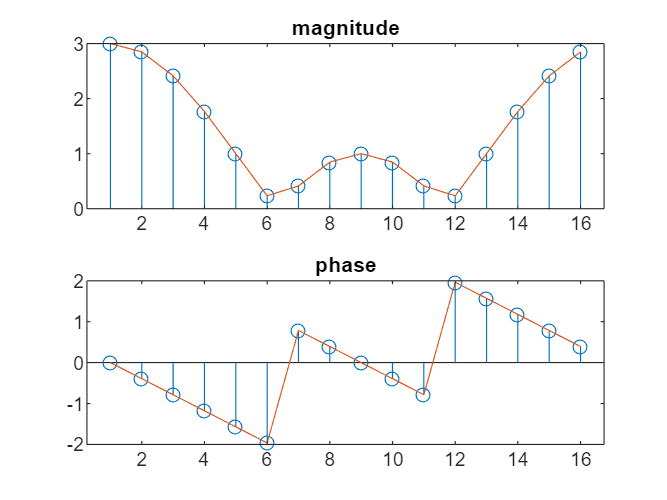

mg = abs(X);
ph = angle(X);
subplot(2,1,1);
stem(mg);
hold on;
plot(mg);
title('magnitude');
subplot(2,1,2);
stem(ph);
hold on;
plot(ph);
title('phase');